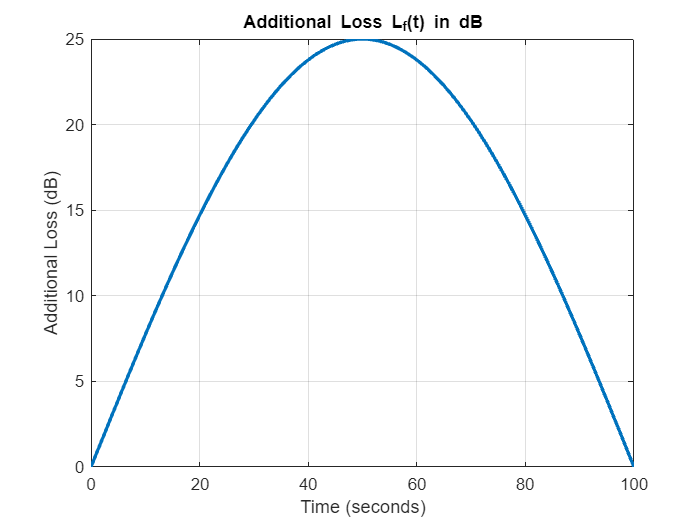

% Question 4
% (a)

time = 0:1:100; % 1 sample/sec sample rate for additional loss function
freq = 0.005;
L_f=25*sin(2*pi*freq.*time);
plot(time,L_f,'LineWidth',2);
title('Additional Loss L_f(t) in dB');
xlabel('Time (seconds)');
ylabel('Additional Loss (dB)');
ylim([0 25]);
grid on;

% (b)

disp('Answer of (b) part starts here');

Answer of (b) part starts here



distance=1000;
frequency=6e9;
t_total=100;
t=0:1:100;

% initializing required arrays for storing variables for each sample
eirp_array = zeros(size(t));
fspl_array = zeros(size(t));
tpl_array = zeros(size(t));
rip_array = zeros(size(t));
ps_array = zeros(size(t));
pn_array = zeros(size(t));
snr_array = zeros(size(t));

%Declaration of Constants and various calculations and conversions.
c=299792458; % speed of light
ff=0.005; % frequency of additional power loss temporal profile
transmit_power=-40; % in dbW

eta_t=0.55; %Antenna Efficiency of Transmitter 
eta_r = 0.5; %Antenna Efficiency of Receiver

diameter_t=1; %Antenna Diameter of Transmitter
diameter_r =0.1; %Antenna Diamter of Receiver

gain_lin_t = eta_t*(pi*diameter_t*frequency/c)^2; %Gain of Transmitter Antenna in linear scale
gain_db_t= 10*log10(gain_lin_t); % Gain of Transmitter Antenna in dB scale 
gain_lin_r = eta_r*(pi*diameter_r*frequency/c)^2; %Gain of Receiver Antenna in linear scale
gain_db_r= 10*log10(gain_lin_r); % Gain of Receiver Antenna in dB scale

temp_c=25; % Ambient Temperature at the receiver in degree Celsius
temp_k=273.15+temp_c; %Ambient Temperature at receiver in Kelvin
temp_k_db = 10*log10(temp_k); % Ambient Temperature at receiver in Kelvin in dB

k = 1.380649e-23; %Boltzmann Constant
k_db = 10*log10(k); %Boltzmann Constant in dB
N_0 = k_db+temp_k_db; % Spectral Density of Noise in dB

B = 125e6; %Bandwidth
B_db = 10*log10(B); %Bandwidth in dB

% Loop to calculate transmit EIRP, Total FSPL, L_f(t), RIP(t), P_s(t), P_n
% and SNR
for i = 1:length(t)
    disp(['Sample ' num2str(i) ':']);
    fspl_array(i) = (4*pi*distance*frequency/c)^2;
    fspl_array(i) = 10*log10(fspl_array(i));
    disp(['  Free Space Path Loss (FSPL): ' num2str(fspl_array(i)) ' dB']);
    Lf_db(i)=25 * sin(2*pi*ff*t(i));
    disp(['  Additional Loss (Lf): ' num2str(Lf_db(i)) ' dB']);
    tpl_array(i)=Lf_db(i)+fspl_array(i);
    disp(['  Total Path Loss (TPL): ' num2str(tpl_array(i)) ' dB']);
    eirp_array(i)=transmit_power+gain_db_t;
    disp(['  Transmit EIRP: ' num2str(eirp_array(i)) ' dBW']);
    rip_array(i) = eirp_array(i)-Lf_db(i)-fspl_array(i);
    disp(['  Received Isotropic Power: ' num2str(rip_array(i)) ' dBW']);
    ps_array(i) = rip_array(i)+gain_db_r;
    disp(['  Received power at receiver antenna (Ps): ' num2str(ps_array(i)) ' dBW']);
    pn_array(i) = N_0+B_db;
    disp(['  Received Noise power: ' num2str(pn_array(i)) ' dBW']);
    snr_array(i) = ps_array(i)-pn_array(i);
    disp(['  SNR = P_S/P_N: ' num2str(snr_array(i)) ' dBW']);
    disp(' ');
end

Sample 1:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 0 dB


  Total Path Loss (TPL): 108.0108 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -114.6376 dBW


  Received power at receiver antenna (Ps): -101.6783 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 21.2075 dBW


Sample 2:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 0.78527 dB


  Total Path Loss (TPL): 108.7961 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -115.4228 dBW


  Received power at receiver antenna (Ps): -102.4635 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 20.4222 dBW


Sample 3:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 1.5698 dB


  Total Path Loss (TPL): 109.5806 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -116.2073 dBW


  Received power at receiver antenna (Ps): -103.248 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 19.6377 dBW


Sample 4:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 2.3527 dB


  Total Path Loss (TPL): 110.3635 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -116.9903 dBW


  Received power at receiver antenna (Ps): -104.031 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 18.8547 dBW


Sample 5:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 3.1333 dB


  Total Path Loss (TPL): 111.1441 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -117.7709 dBW


  Received power at receiver antenna (Ps): -104.8116 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 18.0741 dBW


Sample 6:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 3.9109 dB


  Total Path Loss (TPL): 111.9217 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -118.5484 dBW


  Received power at receiver antenna (Ps): -105.5891 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 17.2966 dBW


Sample 7:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 4.6845 dB


  Total Path Loss (TPL): 112.6953 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -119.3221 dBW


  Received power at receiver antenna (Ps): -106.3628 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 16.5229 dBW


Sample 8:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 5.4536 dB


  Total Path Loss (TPL): 113.4644 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -120.0912 dBW


  Received power at receiver antenna (Ps): -107.1318 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 15.7539 dBW


Sample 9:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 6.2172 dB


  Total Path Loss (TPL): 114.2281 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -120.8548 dBW


  Received power at receiver antenna (Ps): -107.8955 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 14.9902 dBW


Sample 10:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 6.9748 dB


  Total Path Loss (TPL): 114.9856 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -121.6124 dBW


  Received power at receiver antenna (Ps): -108.653 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 14.2327 dBW


Sample 11:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 7.7254 dB


  Total Path Loss (TPL): 115.7362 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -122.363 dBW


  Received power at receiver antenna (Ps): -109.4037 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 13.482 dBW


Sample 12:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 8.4684 dB


  Total Path Loss (TPL): 116.4793 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -123.106 dBW


  Received power at receiver antenna (Ps): -110.1467 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 12.739 dBW


Sample 13:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 9.2031 dB


  Total Path Loss (TPL): 117.2139 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -123.8407 dBW


  Received power at receiver antenna (Ps): -110.8814 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 12.0043 dBW


Sample 14:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 9.9287 dB


  Total Path Loss (TPL): 117.9395 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -124.5663 dBW


  Received power at receiver antenna (Ps): -111.607 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 11.2788 dBW


Sample 15:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 10.6445 dB


  Total Path Loss (TPL): 118.6553 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -125.2821 dBW


  Received power at receiver antenna (Ps): -112.3227 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 10.563 dBW


Sample 16:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 11.3498 dB


  Total Path Loss (TPL): 119.3606 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -125.9873 dBW


  Received power at receiver antenna (Ps): -113.028 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 9.8577 dBW


Sample 17:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 12.0438 dB


  Total Path Loss (TPL): 120.0547 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -126.6814 dBW


  Received power at receiver antenna (Ps): -113.7221 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 9.1636 dBW


Sample 18:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 12.726 dB


  Total Path Loss (TPL): 120.7368 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -127.3636 dBW


  Received power at receiver antenna (Ps): -114.4043 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 8.4814 dBW


Sample 19:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 13.3957 dB


  Total Path Loss (TPL): 121.4065 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -128.0332 dBW


  Received power at receiver antenna (Ps): -115.0739 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 7.8118 dBW


Sample 20:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 14.0521 dB


  Total Path Loss (TPL): 122.0629 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -128.6897 dBW


  Received power at receiver antenna (Ps): -115.7303 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 7.1554 dBW


Sample 21:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 14.6946 dB


  Total Path Loss (TPL): 122.7054 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -129.3322 dBW


  Received power at receiver antenna (Ps): -116.3729 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 6.5128 dBW


Sample 22:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 15.3227 dB


  Total Path Loss (TPL): 123.3335 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -129.9602 dBW


  Received power at receiver antenna (Ps): -117.0009 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 5.8848 dBW


Sample 23:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 15.9356 dB


  Total Path Loss (TPL): 123.9464 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -130.5732 dBW


  Received power at receiver antenna (Ps): -117.6139 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 5.2719 dBW


Sample 24:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 16.5328 dB


  Total Path Loss (TPL): 124.5436 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -131.1704 dBW


  Received power at receiver antenna (Ps): -118.2111 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 4.6747 dBW


Sample 25:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 17.1137 dB


  Total Path Loss (TPL): 125.1245 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -131.7513 dBW


  Received power at receiver antenna (Ps): -118.7919 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 4.0938 dBW


Sample 26:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 17.6777 dB


  Total Path Loss (TPL): 125.6885 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -132.3152 dBW


  Received power at receiver antenna (Ps): -119.3559 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 3.5298 dBW


Sample 27:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 18.2242 dB


  Total Path Loss (TPL): 126.235 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -132.8618 dBW


  Received power at receiver antenna (Ps): -119.9025 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 2.9832 dBW


Sample 28:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 18.7528 dB


  Total Path Loss (TPL): 126.7636 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -133.3903 dBW


  Received power at receiver antenna (Ps): -120.431 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 2.4547 dBW


Sample 29:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 19.2628 dB


  Total Path Loss (TPL): 127.2736 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -133.9004 dBW


  Received power at receiver antenna (Ps): -120.9411 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 1.9446 dBW


Sample 30:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 19.7539 dB


  Total Path Loss (TPL): 127.7647 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -134.3914 dBW


  Received power at receiver antenna (Ps): -121.4321 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 1.4536 dBW


Sample 31:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 20.2254 dB


  Total Path Loss (TPL): 128.2362 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -134.863 dBW


  Received power at receiver antenna (Ps): -121.9037 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 0.98203 dBW


Sample 32:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 20.677 dB


  Total Path Loss (TPL): 128.6878 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -135.3146 dBW


  Received power at receiver antenna (Ps): -122.3553 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 0.53044 dBW


Sample 33:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 21.1082 dB


  Total Path Loss (TPL): 129.119 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -135.7458 dBW


  Received power at receiver antenna (Ps): -122.7865 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 0.099256 dBW


Sample 34:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 21.5186 dB


  Total Path Loss (TPL): 129.5294 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -136.1561 dBW


  Received power at receiver antenna (Ps): -123.1968 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -0.3111 dBW


Sample 35:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 21.9077 dB


  Total Path Loss (TPL): 129.9185 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -136.5452 dBW


  Received power at receiver antenna (Ps): -123.5859 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -0.70021 dBW


Sample 36:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 22.2752 dB


  Total Path Loss (TPL): 130.286 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -136.9127 dBW


  Received power at receiver antenna (Ps): -123.9534 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -1.0677 dBW


Sample 37:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 22.6207 dB


  Total Path Loss (TPL): 130.6315 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -137.2582 dBW


  Received power at receiver antenna (Ps): -124.2989 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -1.4132 dBW


Sample 38:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 22.9439 dB


  Total Path Loss (TPL): 130.9547 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -137.5814 dBW


  Received power at receiver antenna (Ps): -124.6221 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -1.7364 dBW


Sample 39:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 23.2444 dB


  Total Path Loss (TPL): 131.2552 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -137.882 dBW


  Received power at receiver antenna (Ps): -124.9227 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -2.037 dBW


Sample 40:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 23.522 dB


  Total Path Loss (TPL): 131.5328 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -138.1596 dBW


  Received power at receiver antenna (Ps): -125.2003 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -2.3146 dBW


Sample 41:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 23.7764 dB


  Total Path Loss (TPL): 131.7872 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -138.414 dBW


  Received power at receiver antenna (Ps): -125.4547 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -2.569 dBW


Sample 42:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 24.0073 dB


  Total Path Loss (TPL): 132.0182 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -138.6449 dBW


  Received power at receiver antenna (Ps): -125.6856 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -2.7999 dBW


Sample 43:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 24.2146 dB


  Total Path Loss (TPL): 132.2254 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -138.8522 dBW


  Received power at receiver antenna (Ps): -125.8928 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -3.0071 dBW


Sample 44:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 24.3979 dB


  Total Path Loss (TPL): 132.4087 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -139.0355 dBW


  Received power at receiver antenna (Ps): -126.0762 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -3.1905 dBW


Sample 45:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 24.5572 dB


  Total Path Loss (TPL): 132.568 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -139.1948 dBW


  Received power at receiver antenna (Ps): -126.2354 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -3.3497 dBW


Sample 46:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 24.6922 dB


  Total Path Loss (TPL): 132.703 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -139.3298 dBW


  Received power at receiver antenna (Ps): -126.3705 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -3.4848 dBW


Sample 47:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 24.8029 dB


  Total Path Loss (TPL): 132.8137 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -139.4404 dBW


  Received power at receiver antenna (Ps): -126.4811 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -3.5954 dBW


Sample 48:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 24.889 dB


  Total Path Loss (TPL): 132.8999 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -139.5266 dBW


  Received power at receiver antenna (Ps): -126.5673 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -3.6816 dBW


Sample 49:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 24.9507 dB


  Total Path Loss (TPL): 132.9615 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -139.5882 dBW


  Received power at receiver antenna (Ps): -126.6289 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -3.7432 dBW


Sample 50:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 24.9877 dB


  Total Path Loss (TPL): 132.9985 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -139.6252 dBW


  Received power at receiver antenna (Ps): -126.6659 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -3.7802 dBW


Sample 51:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 25 dB


  Total Path Loss (TPL): 133.0108 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -139.6376 dBW


  Received power at receiver antenna (Ps): -126.6783 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -3.7925 dBW


Sample 52:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 24.9877 dB


  Total Path Loss (TPL): 132.9985 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -139.6252 dBW


  Received power at receiver antenna (Ps): -126.6659 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -3.7802 dBW


Sample 53:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 24.9507 dB


  Total Path Loss (TPL): 132.9615 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -139.5882 dBW


  Received power at receiver antenna (Ps): -126.6289 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -3.7432 dBW


Sample 54:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 24.889 dB


  Total Path Loss (TPL): 132.8999 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -139.5266 dBW


  Received power at receiver antenna (Ps): -126.5673 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -3.6816 dBW


Sample 55:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 24.8029 dB


  Total Path Loss (TPL): 132.8137 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -139.4404 dBW


  Received power at receiver antenna (Ps): -126.4811 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -3.5954 dBW


Sample 56:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 24.6922 dB


  Total Path Loss (TPL): 132.703 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -139.3298 dBW


  Received power at receiver antenna (Ps): -126.3705 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -3.4848 dBW


Sample 57:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 24.5572 dB


  Total Path Loss (TPL): 132.568 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -139.1948 dBW


  Received power at receiver antenna (Ps): -126.2354 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -3.3497 dBW


Sample 58:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 24.3979 dB


  Total Path Loss (TPL): 132.4087 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -139.0355 dBW


  Received power at receiver antenna (Ps): -126.0762 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -3.1905 dBW


Sample 59:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 24.2146 dB


  Total Path Loss (TPL): 132.2254 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -138.8522 dBW


  Received power at receiver antenna (Ps): -125.8928 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -3.0071 dBW


Sample 60:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 24.0073 dB


  Total Path Loss (TPL): 132.0182 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -138.6449 dBW


  Received power at receiver antenna (Ps): -125.6856 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -2.7999 dBW


Sample 61:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 23.7764 dB


  Total Path Loss (TPL): 131.7872 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -138.414 dBW


  Received power at receiver antenna (Ps): -125.4547 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -2.569 dBW


Sample 62:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 23.522 dB


  Total Path Loss (TPL): 131.5328 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -138.1596 dBW


  Received power at receiver antenna (Ps): -125.2003 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -2.3146 dBW


Sample 63:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 23.2444 dB


  Total Path Loss (TPL): 131.2552 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -137.882 dBW


  Received power at receiver antenna (Ps): -124.9227 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -2.037 dBW


Sample 64:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 22.9439 dB


  Total Path Loss (TPL): 130.9547 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -137.5814 dBW


  Received power at receiver antenna (Ps): -124.6221 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -1.7364 dBW


Sample 65:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 22.6207 dB


  Total Path Loss (TPL): 130.6315 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -137.2582 dBW


  Received power at receiver antenna (Ps): -124.2989 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -1.4132 dBW


Sample 66:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 22.2752 dB


  Total Path Loss (TPL): 130.286 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -136.9127 dBW


  Received power at receiver antenna (Ps): -123.9534 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -1.0677 dBW


Sample 67:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 21.9077 dB


  Total Path Loss (TPL): 129.9185 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -136.5452 dBW


  Received power at receiver antenna (Ps): -123.5859 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -0.70021 dBW


Sample 68:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 21.5186 dB


  Total Path Loss (TPL): 129.5294 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -136.1561 dBW


  Received power at receiver antenna (Ps): -123.1968 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: -0.3111 dBW


Sample 69:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 21.1082 dB


  Total Path Loss (TPL): 129.119 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -135.7458 dBW


  Received power at receiver antenna (Ps): -122.7865 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 0.099256 dBW


Sample 70:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 20.677 dB


  Total Path Loss (TPL): 128.6878 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -135.3146 dBW


  Received power at receiver antenna (Ps): -122.3553 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 0.53044 dBW


Sample 71:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 20.2254 dB


  Total Path Loss (TPL): 128.2362 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -134.863 dBW


  Received power at receiver antenna (Ps): -121.9037 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 0.98203 dBW


Sample 72:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 19.7539 dB


  Total Path Loss (TPL): 127.7647 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -134.3914 dBW


  Received power at receiver antenna (Ps): -121.4321 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 1.4536 dBW


Sample 73:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 19.2628 dB


  Total Path Loss (TPL): 127.2736 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -133.9004 dBW


  Received power at receiver antenna (Ps): -120.9411 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 1.9446 dBW


Sample 74:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 18.7528 dB


  Total Path Loss (TPL): 126.7636 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -133.3903 dBW


  Received power at receiver antenna (Ps): -120.431 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 2.4547 dBW


Sample 75:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 18.2242 dB


  Total Path Loss (TPL): 126.235 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -132.8618 dBW


  Received power at receiver antenna (Ps): -119.9025 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 2.9832 dBW


Sample 76:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 17.6777 dB


  Total Path Loss (TPL): 125.6885 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -132.3152 dBW


  Received power at receiver antenna (Ps): -119.3559 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 3.5298 dBW


Sample 77:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 17.1137 dB


  Total Path Loss (TPL): 125.1245 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -131.7513 dBW


  Received power at receiver antenna (Ps): -118.7919 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 4.0938 dBW


Sample 78:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 16.5328 dB


  Total Path Loss (TPL): 124.5436 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -131.1704 dBW


  Received power at receiver antenna (Ps): -118.2111 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 4.6747 dBW


Sample 79:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 15.9356 dB


  Total Path Loss (TPL): 123.9464 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -130.5732 dBW


  Received power at receiver antenna (Ps): -117.6139 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 5.2719 dBW


Sample 80:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 15.3227 dB


  Total Path Loss (TPL): 123.3335 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -129.9602 dBW


  Received power at receiver antenna (Ps): -117.0009 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 5.8848 dBW


Sample 81:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 14.6946 dB


  Total Path Loss (TPL): 122.7054 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -129.3322 dBW


  Received power at receiver antenna (Ps): -116.3729 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 6.5128 dBW


Sample 82:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 14.0521 dB


  Total Path Loss (TPL): 122.0629 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -128.6897 dBW


  Received power at receiver antenna (Ps): -115.7303 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 7.1554 dBW


Sample 83:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 13.3957 dB


  Total Path Loss (TPL): 121.4065 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -128.0332 dBW


  Received power at receiver antenna (Ps): -115.0739 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 7.8118 dBW


Sample 84:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 12.726 dB


  Total Path Loss (TPL): 120.7368 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -127.3636 dBW


  Received power at receiver antenna (Ps): -114.4043 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 8.4814 dBW


Sample 85:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 12.0438 dB


  Total Path Loss (TPL): 120.0547 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -126.6814 dBW


  Received power at receiver antenna (Ps): -113.7221 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 9.1636 dBW


Sample 86:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 11.3498 dB


  Total Path Loss (TPL): 119.3606 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -125.9873 dBW


  Received power at receiver antenna (Ps): -113.028 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 9.8577 dBW


Sample 87:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 10.6445 dB


  Total Path Loss (TPL): 118.6553 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -125.2821 dBW


  Received power at receiver antenna (Ps): -112.3227 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 10.563 dBW


Sample 88:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 9.9287 dB


  Total Path Loss (TPL): 117.9395 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -124.5663 dBW


  Received power at receiver antenna (Ps): -111.607 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 11.2788 dBW


Sample 89:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 9.2031 dB


  Total Path Loss (TPL): 117.2139 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -123.8407 dBW


  Received power at receiver antenna (Ps): -110.8814 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 12.0043 dBW


Sample 90:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 8.4684 dB


  Total Path Loss (TPL): 116.4793 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -123.106 dBW


  Received power at receiver antenna (Ps): -110.1467 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 12.739 dBW


Sample 91:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 7.7254 dB


  Total Path Loss (TPL): 115.7362 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -122.363 dBW


  Received power at receiver antenna (Ps): -109.4037 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 13.482 dBW


Sample 92:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 6.9748 dB


  Total Path Loss (TPL): 114.9856 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -121.6124 dBW


  Received power at receiver antenna (Ps): -108.653 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 14.2327 dBW


Sample 93:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 6.2172 dB


  Total Path Loss (TPL): 114.2281 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -120.8548 dBW


  Received power at receiver antenna (Ps): -107.8955 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 14.9902 dBW


Sample 94:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 5.4536 dB


  Total Path Loss (TPL): 113.4644 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -120.0912 dBW


  Received power at receiver antenna (Ps): -107.1318 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 15.7539 dBW


Sample 95:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 4.6845 dB


  Total Path Loss (TPL): 112.6953 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -119.3221 dBW


  Received power at receiver antenna (Ps): -106.3628 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 16.5229 dBW


Sample 96:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 3.9109 dB


  Total Path Loss (TPL): 111.9217 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -118.5484 dBW


  Received power at receiver antenna (Ps): -105.5891 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 17.2966 dBW


Sample 97:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 3.1333 dB


  Total Path Loss (TPL): 111.1441 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -117.7709 dBW


  Received power at receiver antenna (Ps): -104.8116 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 18.0741 dBW


Sample 98:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 2.3527 dB


  Total Path Loss (TPL): 110.3635 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -116.9903 dBW


  Received power at receiver antenna (Ps): -104.031 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 18.8547 dBW


Sample 99:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 1.5698 dB


  Total Path Loss (TPL): 109.5806 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -116.2073 dBW


  Received power at receiver antenna (Ps): -103.248 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 19.6377 dBW


Sample 100:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): 0.78527 dB


  Total Path Loss (TPL): 108.7961 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -115.4228 dBW


  Received power at receiver antenna (Ps): -102.4635 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 20.4222 dBW


Sample 101:


  Free Space Path Loss (FSPL): 108.0108 dB


  Additional Loss (Lf): -8.0406e-15 dB


  Total Path Loss (TPL): 108.0108 dB


  Transmit EIRP: -6.6268 dBW


  Received Isotropic Power: -114.6376 dBW


  Received power at receiver antenna (Ps): -101.6783 dBW


  Received Noise power: -122.8857 dBW


  SNR = P_S/P_N: 21.2075 dBW


% (c)

%To simplify our variable names we have renamed the file as modcod and the
%table columns as SNR and etab.

modcod = readtable('modcod.xlsx', 'VariableNamingRule', 'preserve');
etab = zeros(size(t));
achievedDataRate = zeros(size(t));

bandwidth = 125e6;
for i = 1:length(t)
    [~, idx] = max(modcod.SNR(modcod.SNR <= snr_array(i)));
    etab(i) = modcod.etab(idx);
    achievedDataRate(i) = etab(i) * bandwidth;
end

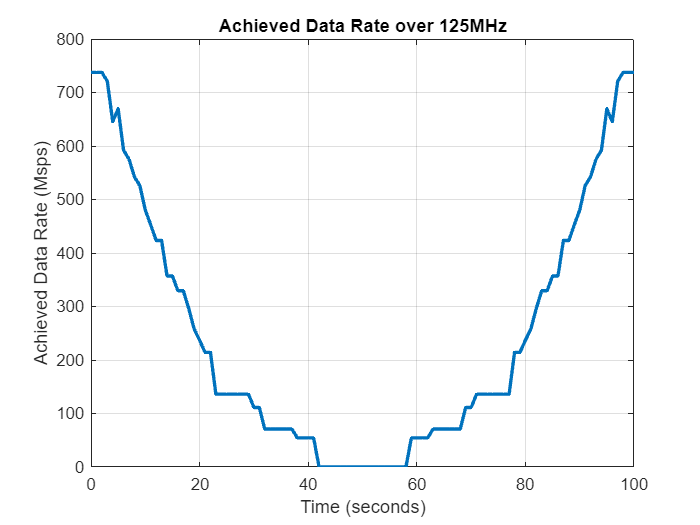

% (d)

% Convert achieved data rate to Mbps
achievedDataRateMbps = achievedDataRate / 1e6;

plot(t, achievedDataRateMbps,'LineWidth',2);
xlabel('Time (seconds)');
ylabel('Achieved Data Rate (Msps)');
title('Achieved Data Rate over 125MHz');
grid("on");

disp(" ");

% Question 5
% MIMO CONCEPT

%1)
% Specify the number of receive antennas (N_R) and transmit antennas (N_T)
NR = 8;  % Number of receive antennas
NT = 16;  % Number of transmit antennas

% Generate a random complex-valued matrix with dimensions (N_R, N_T)
real_part = randn(NR, NT);
imag_part = randn(NR, NT);
H = real_part + 1i * imag_part;  % Complex matrix
H=H/sqrt(2);

% Display the generated MIMO channel matrix
disp('MIMO Channel Matrix H:');

MIMO Channel Matrix H:


disp(H);

   0.7655 + 0.4944i  -0.0388 - 0.2050i  -0.4607 + 0.5788i  -0.0501 - 0.0451i   0.4787 - 0.1840i  -0.0933 - 0.2311i   0.5839 + 1.1568i  -0.1250 - 0.7911i  -0.3965 + 0.1408i   0.5287 + 0.5766i   0.2285 - 0.4270i  -0.6397 - 0.1685i  -0.7474 - 0.4303i  -0.6397 + 0.2056i   0.3031 - 0.7731i  -0.2202 + 0.8648i
   0.7114 + 0.1907i   0.6443 + 0.8921i   0.8429 - 0.2069i  -1.7581 + 0.4323i   0.6065 + 0.4244i  -0.1041 + 0.5744i  -0.7177 - 0.3006i  -1.5076 - 0.4429i   1.5399 - 1.0755i  -0.1931 + 0.5649i  -0.5545 + 0.1251i  -0.3307 + 0.1623i  -0.2009 - 0.5212i  -0.2038 + 0.0799i  -0.7326 - 0.3066i  -0.4031 - 0.9074i
  -0.4603 + 0.3495i   0.4204 + 0.3362i  -1.1397 - 0.3824i   0.4110 + 0.0773i  -0.4887 + 0.4200i   0.7126 + 0.3858i  -0.3331 + 0.4168i   0.8099 + 0.1764i   0.8050 - 0.5117i   1.1146 + 0.0850i  -1.2766 - 0.2174i  -0.0883 + 0.3111i  -0.0613 - 1.2374i   0.2475 + 0.3111i   1.3279 - 0.1191i  -0.7253 - 1.6468i
   0.1818 - 1.0487i   0.2476 + 0.8302i  -0.0173 - 0.2182i  -1.5503 + 1.2827i   0.3178

%2)
% Using M-PSK method to generate symbols
%Add a file which contains the function pskModulator for generating a set
%of M-ary Phase Shift Keying Modulation Scheme.

symbols_PSK=pskModulator(16,1);

%3)
% N_R generated randomly from M symbols
all_indices = 1:length(symbols_PSK);
selected_indices = all_indices(randperm(length(all_indices), NR));
selected_symbols = symbols_PSK(selected_indices);

% N_T*1 Matrix
x = zeros(NT, 1);
x(1:NR) = selected_symbols;

%4)
% Received signal vector
y = H * x;

%5)
%The elements of y do not match with the elements of x before peforming
%operation with MIMO channel matrix.
disp('Before performing smart MIMO scheme')

Before performing smart MIMO scheme


disp('Transmitted Symbol Vector x:');

Transmitted Symbol Vector x:


disp(x.');

  -0.7071 + 0.7071i  -0.9239 - 0.3827i  -0.3827 + 0.9239i   0.7071 + 0.7071i  -0.3827 - 0.9239i   0.3827 - 0.9239i   1.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i



disp('Received Signal Vector y:');

Received Signal Vector y:


disp(y.');

  -0.5229 + 0.3393i  -2.1959 - 2.9969i   1.5385 - 0.5987i  -3.1053 + 0.7981i  -1.5388 - 3.9138i  -2.0506 + 1.0852i  -1.2943 + 0.7107i   0.8186 - 1.4923i



% 6)
% Performing SVD and obtaining matrices on left U and right V singular
% vectors and a diagonal matrix of the singular values S.
%Performing a Smary MIMO Scheme
[U, S, V] = svd(H);

%Verifying that U and V matrices are unitary
tolerance = 1e-10;  % Set a small tolerance value
is_U_unitary = norm(U' * U - eye(NR)) < tolerance;
is_V_unitary = norm(V' * V - eye(NT)) < tolerance;

% Collecting these non-zero elements in S
nonzero_elements_S = diag(S);
num_nonzero_elements_S = sum(nonzero_elements_S ~= 0); % equal to NR

%7)
% Display the results and verifying whether U and V are unitary and 
% Non-zero elements in S equals NR
disp('SVD Results:');

SVD Results:


disp(['U is unitary: ', num2str(is_U_unitary)]);

U is unitary: 1


disp(['V is unitary: ', num2str(is_V_unitary)]);

V is unitary: 1


disp(['Number of nonzero elements in S: ', num2str(num_nonzero_elements_S)]);

Number of nonzero elements in S: 8


disp('Nonzero elements of S:');

Nonzero elements of S:


disp(nonzero_elements_S.');

    5.8991    5.7249    4.2700    3.4637    3.0313    2.4774    2.1908    1.3276



%(a)
x_prime= V*x;

%(b)
y_prime=H*x_prime;

%(c)
U_herm=U';
y=U_herm* y_prime;

%(d)
% Element by element division
y_S=y./nonzero_elements_S;

%(e)
% Display the results
disp('Transmitted Vector x:');

Transmitted Vector x:


disp(x.');

  -0.7071 + 0.7071i  -0.9239 - 0.3827i  -0.3827 + 0.9239i   0.7071 + 0.7071i  -0.3827 - 0.9239i   0.3827 - 0.9239i   1.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i



disp('Transmitted Vector x'' (after MIMO):');

Transmitted Vector x' (after MIMO):


disp(x_prime.');

   0.2672 - 0.0340i   0.1819 + 0.2649i   0.0593 + 0.4289i  -0.4736 - 0.3641i   1.1709 - 0.5082i   0.8539 - 0.1097i   0.5614 - 0.6877i   0.5685 + 0.0169i  -0.3456 + 0.2340i   0.9749 - 0.3821i  -0.5917 + 0.0805i  -0.4057 + 0.2184i  -0.2108 + 0.6690i  -0.4785 + 0.3456i   0.2023 + 0.4653i  -0.8716 + 0.3178i



disp('Received Vector y'' (after MIMO):');

Received Vector y' (after MIMO):


disp(y_prime.');

   3.4818 - 2.0644i   1.9058 + 3.1088i   4.4510 + 3.0100i  -0.4823 - 4.0465i  -1.6276 - 0.8347i  -0.1388 - 4.7917i   0.1268 + 3.9686i   0.5034 - 1.4792i



disp('Received Vector y (after receive side "beamforming"):');

Received Vector y (after receive side "beamforming"):


disp(y.');

  -4.1713 + 4.1713i  -5.2891 - 2.1908i  -1.6341 + 3.9450i   2.4492 + 2.4492i  -1.1600 - 2.8005i   0.9481 - 2.2888i   2.1908 + 0.0000i   0.0000 + 1.3276i



disp('Element-by-element Division Result y_s:');

Element-by-element Division Result y_s:


disp(y_S.');

  -0.7071 + 0.7071i  -0.9239 - 0.3827i  -0.3827 + 0.9239i   0.7071 + 0.7071i  -0.3827 - 0.9239i   0.3827 - 0.9239i   1.0000 + 0.0000i   0.0000 + 1.0000i



disp('We can see that y_S and x are identical from the output which is desired as interference introduced by the MIMO channel has been entirely removed thereby increasing the channel capacity by factor or N_R.');

We can see that y_S and x are identical from the output which is desired as interference introduced by the MIMO channel has been entirely removed thereby increasing the channel capacity by factor or N_R.


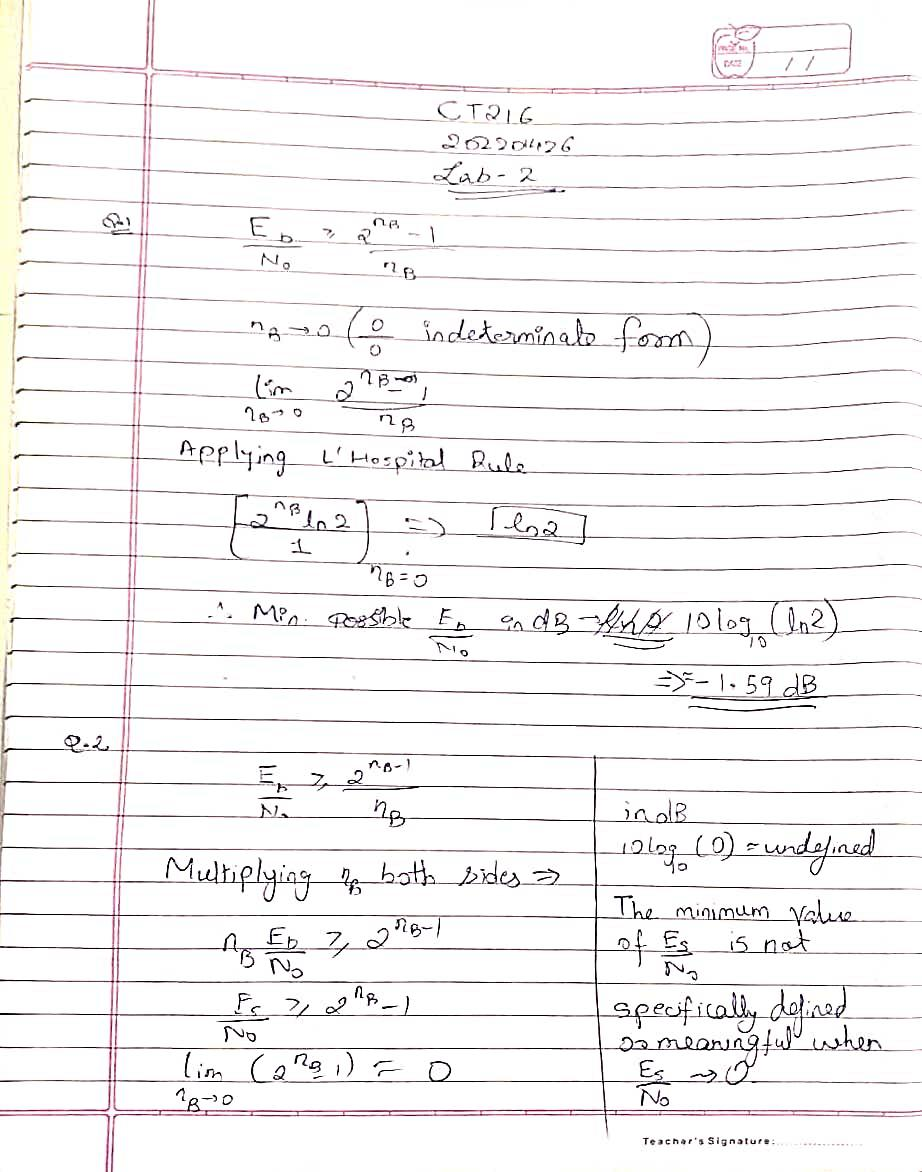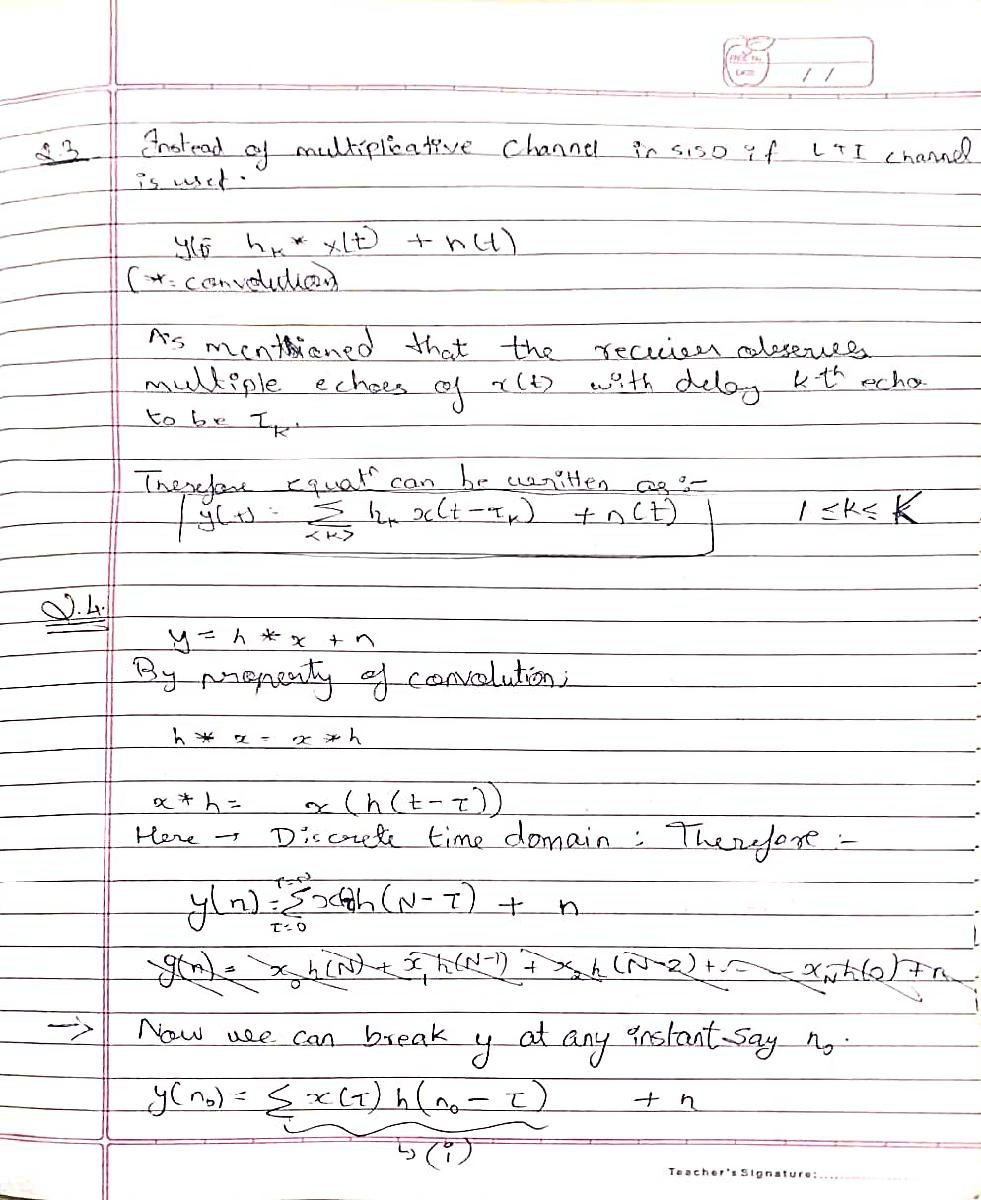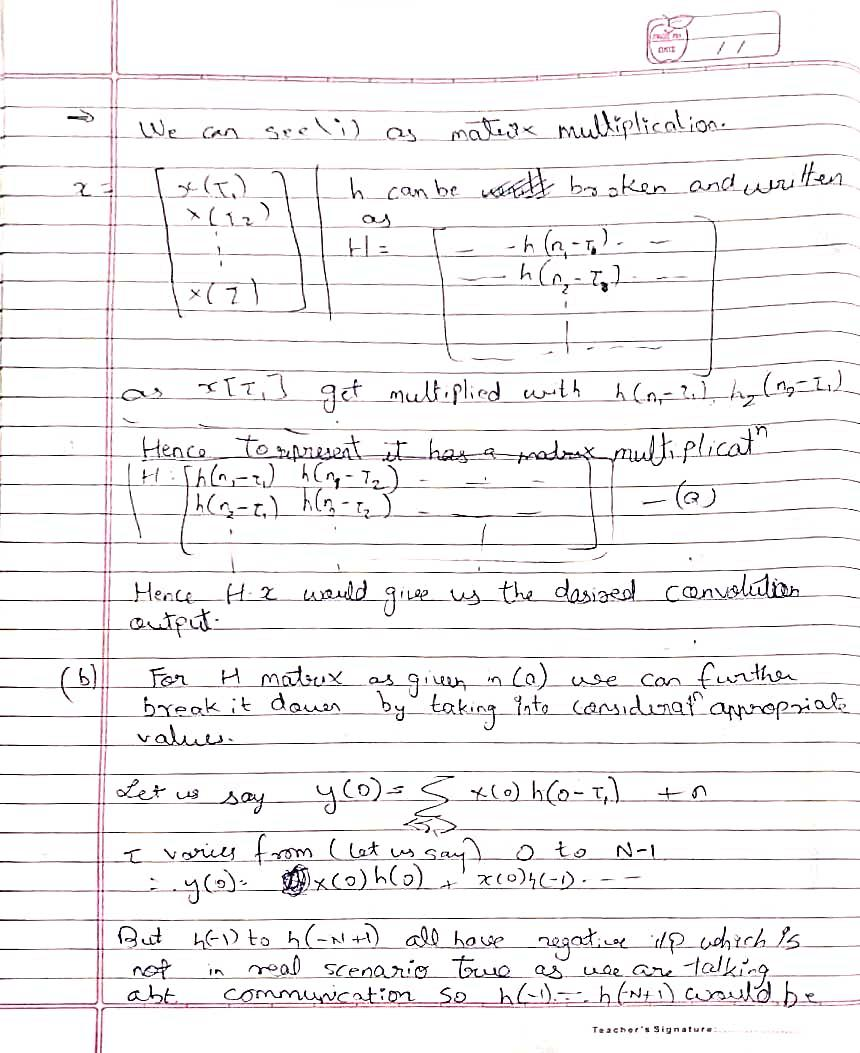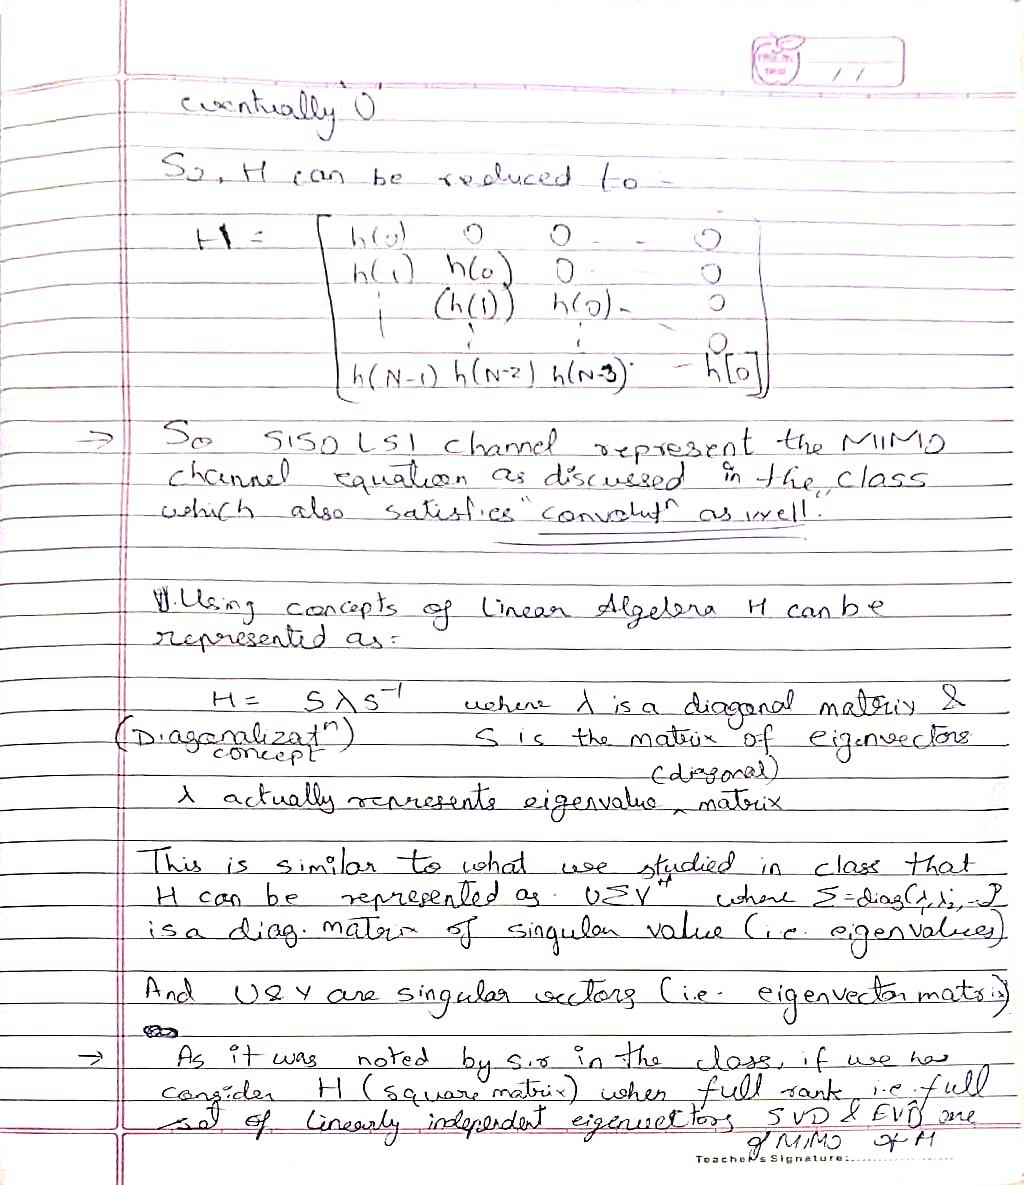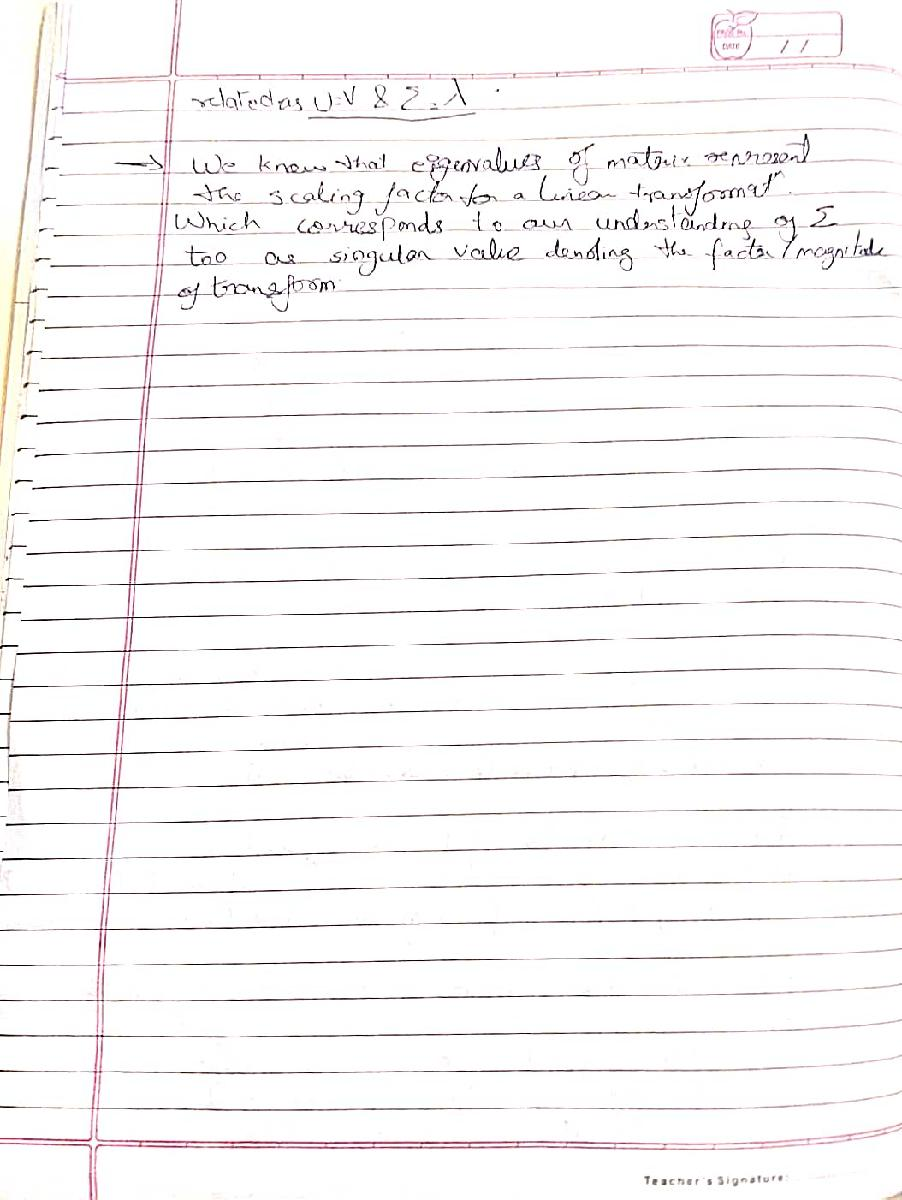

%{ 
for question 4 part (b) it is also important to note that EVD is possible
when H is a square matrix.

Also it is analytically difficult to obtain the eigen values and eigen
vectors for H but can be done computationally in MATLAB if provided with
proper values.

Furthermore eigen vectors here in this case may represent the directions in
which communication is done.


%} 